**Co**ntinuation of **S**olution **T**orus **A**pp**R**oximations

[Engineering Dynamics Group, Institute for Mechanics, University of Kassel, Germany](https://www.uni-kassel.de/maschinenbau/institute/mechanik/fachgebiete/technische-dynamik/startseite)

# Tutorial: Postprocessing Function `solget`

## Welcome to the CoSTAR Tutorials!

In this tutorial, we will look at the postprocessing functions `solget` and how to use it. `solget` is used to obtain solutions data, which can be further used for individual purposes, in different *solution spaces* without plotting.

Apart from `solget`, there are also the postprocessing methods `contplot` for creating continuation (bifurcation) diagrams and `solplot` for plotting individual solutions. These methods also return the plotted data points. To learn about `contplot` and `solplot`, please see the corresponding tutorials.

Of course, we need a solution computed by CoSTAR before we can use the postprocessing functions, so we start with a continuation in order to have a set of solutions at hand. After that, we will have a detailed look at `solget`.

## Computing solutions to work with

In this tutorial, we use the periodically forced *Duffing* oscillator $x^{\prime\prime} + 2Dx{\prime} + x + \kappa x^3 = g \cos (\eta \tau)$ as an example. The continuation parameter $\mu$ will be the excitation frequency $\eta$ and we will use the shooting method to approximate the solutions.

Before we can use CoSTAR, we need to add the main CoSTAR folder (and all subfolders) to MATLAB's search path. Assuming you are running this script within the *Tutorials* subfolder of CoSTAR, this is done by:

% addpath(genpath('..\'))           % genpath() generates a search path containing all subfolders

(Note: The command above is set as comment in order to prevent unwanted folders to be added to MATLAB's search path in case that the current path is not the *Tutorials* subfolder.)

Now we are set to perform a continuation of the periodically forced *Duffing* oscillator using the shooting method. The following code is taken from *Example_PS_SHM *and not explained any further at this point. If you are new to CoSTAR, it is advised to go through the corresponding example within the tutorial on periodic solutions approximated by the shooting method (see *Tutorial_PS_SHM*, chapter 1) before continuing with this tutorial.


                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0          4           0.0292105                           0.171              1
     1          8           3.649e-18       0.170911         1.42e-09              1

Equation solved. The sum of squared function values, r = 3.648999e-18, is less than
sqrt(options.FunctionTolerance) = 1.000000e-03. The relative norm of the gradient of r,
1.423941e-09, is less than options.OptimalityTolerance = 1.000000e-06.

-------------------------------------------------------
--------------- Initial solution found! ---------------
-------------------------------------------------------
Iter: 2 -- mu = 0.1100 -- stepwidth = 0.1000
Iter: 3 -- mu = 0.1642 -- stepwidth = 0.0500
Iter: 4 -- mu = 0.1729 -- stepwidth = 0.0250
Iter: 5 -- mu = 0.1903 -- stepwidth =

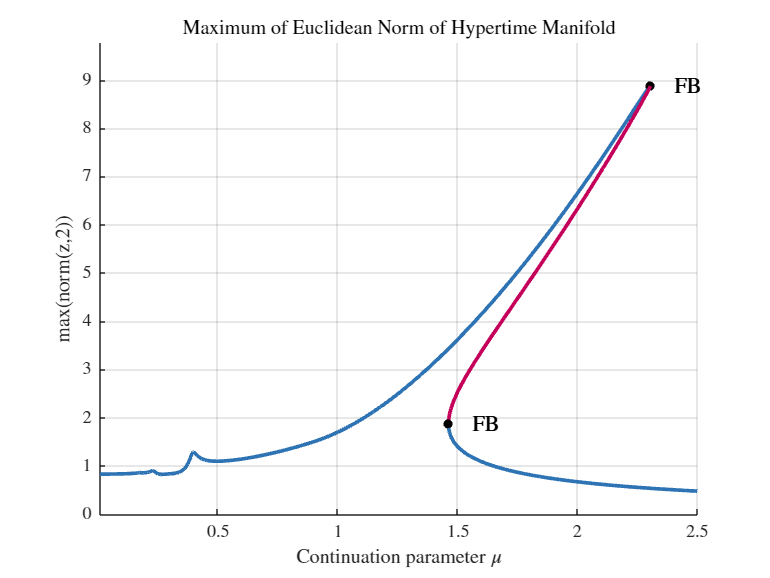

Iter: 239 -- mu = 2.6088 -- stepwidth = 0.1575
Maximal value of continuation parameter mu_max = 2.5 reached: mu = 2.6088


clear variables; clc; close all;                    % clear workspace; clear command window; close all figures

% Parameters
D = 0.05;     kappa = 0.3;     g = 1;               % Parameters needed for the Duffing differential equation
mu_limit = [0.01, 2.5];                             % Limits of the continuation        
eta0 = mu_limit(1);                                 % Value of continuation parameter at start of continuation
param = {kappa, D, eta0, g};                        % Parameter array
active_parameter = 3;                               % Location of continuation parameter within the array
IC = [1; 0];                                        % Initial condition (point in state space) for fsolve

% Functions
non_auto_freq = @(mu) mu;                           % Non-autonomous excitation frequency
Fcn =  @(t,z,param) duffing_ap(t,z,param);          % Right-hand side of dz/dtau = f(tau,z,kappa,D,eta,g)

% Options
options.system = costaropts('order',1,'dim',2,'rhs',Fcn,'param',param,'info','continuation of Duffing equation');   % Properties of the system
options.opt_sol = costaropts('sol_type','periodic','approx_method','shooting','cont','on','stability','on', ...     % Properties of the solution
                             'non_auto_freq',non_auto_freq,'act_param',active_parameter);                           % Properties of the solution
options.opt_init = costaropts('ic',IC);                                                                             % Property for initial solution
options.opt_approx_method = costaropts('solver','ode45');                                                           % Properties of approximation method
options.opt_cont = costaropts('mu_limit',mu_limit);                                                                 % Properties for continuation

% Continuation
[S,DYN] = costar(options);                          % CoSTAR is called by costar(options)

Alright, now we have enough solutions to work with and we can begin with the actual tutorial on the postprocessing method `solget`.

# `solget`

The postprocessing function `solget` is used to obtain solution data in different *solution spaces*. In particular, three different solution spaces are available:

- ***Time*****:**              The solution data is returned with respect to time $t$

- ***Hypertime*****:**     The solution data is returned with respect to hypertime $\theta$ (periodic case) or $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$ (quasi-periodic case)

- ***Frequency*****:**    The frequency content of a solution is returned

Note: The solution space *trajectory*, which is available for the postprocessing method `solplot`, is not necessary here as a trajectory can easily be created based on a solution parametrized in time $t$.

## General syntax

`solget` is used in the following way:

### **Input arguments**

- `DYN`**:** `DynamicalSystem` object returned by the `costar` function. Must correspond to `Solution` object `S`, which is also returned by the `costar` function.

- `solget_options`**:** Structure defining the necessary options. Must be created using the `costaropts` function. In case of any invalid entry, the CoSTAR *Gatekeeper* will throw an error.

### **Output arguments**

The four output arguments depend on the selected solution space in which the solution is returned. 

Please note that the returned `options` structure can change within `solget`. The input `options` structure may therefore not be the same as the output `options` structure.

The specific meaning of the evaluated solution data and of the returned frequency content depend on the requested evaluation of the solution, which is defined via the options field `'eval'`. For instance, the retunred data can be the solution of the first state variable $z_1$ or the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables. Further explanations of `'eval'` can be found in the subsection **Mandatory fields** below.

The individual array sizes of the different outputs depend on the solution space, the solution type (equilibrium, periodic or quasi-periodic), the requested evaluation, the number of different solutions to evaluate and the desired resolution of the evaluated solution. An overview on the array sizes is given by the table below, where

- `n_sol` is the number of different solutions (in context of a continuation) to evaluate. The number corresponds to the field `'index'` via `n_sol = numel(options.index)` (further explanations of `'index'` can be found in the subsection **Optional fields** below).

- `dim_eval_z` corresponds to the dimension of the evaluated state vector $\mathbf z$ for each solution (in context of a continuation). It is determined by the value of the options field `'eval'` (see subsection **Mandatory fields** below). In case of `options.eval = 'all'`, `dim_eval_z` is equal to the dimension $d$ of the system since all state variables of a solution are returned. For `options.eval = 'euclidean'`, `dim_eval_z` equals 1 since the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables is returned. If `options.eval` is set as individual *function handle*, `dim_eval_z` is equal to the dimension of the output of the defined function handle.

- `res` is the resolution, i.e. the number of data points of an evaluated solution along the underlying time or hypertime domain. `res` can be set via the options field `'resolution'` (see subsection **Optional fields** below).

- `floor()` is a MATLAB function rounding each element to the nearest integer less than or equal to that element.

The structure of the output arrays is overall fairly similar and can easily be understood by the table and explanation above.

- All array dimensions of size `res` correspond to time $t$ or hypertime $\theta$ (periodic solutions / 1D manifolds). For *quasi-periodic hypertime* solution space (2D manifolds), there are two array dimensions `res_1` and `res_2` since the solutions are parametrized in hypertime coordinates $\theta_1$ and $\theta_2$. Naturally, `res_1` corresponds to hypertime $\theta_1$ and `res_2` corresponds to hypertime $\theta_2$. For *equilibrium hypertime* solution space, a corresponding array dimension is missing since equilibrium solutions (isolated points in state space) can be represented by a 0D torus without any dimension, making a resolution superfluous.

- For *frequency* solution space, the array dimensions of size `floor(res/2)` correspond to the angular frequency $\omega$ (in context of the frequency content of a solution) as a Fast-Fourier-Transformation (FFT) is carried out when plotting in *frequency* solution space.

- All array dimensions of size `dim_eval_z` either correspond to the state variables of a system (in case of `options.eval = 'all')` or they correspond to the Euclidean norm $\Vert \mathbf z \Vert$ of all state variables (in case of `options.eval = 'euclidean')` or they correspond to the output of the defined function handle in `options.eval`.

- All array dimensions of size `n_sol` correspond to the different solutions (in context of a continuation) that are returned. If there is only one solution to return (`n_sol = 1`), the corresponding array dimension is not present. For instance, the array size of `output_1` in *time* solution space is only `[res x dim_eval_z]` in this case.

After having discussed the input and output arguments of `solget`, we turn to the available options fields. It may be advisable to go through the section on the **Output arguments** again after reading the next section **Options**, as some explanations may then become clearer.

## Options

All settings for `solget` are defined via a structure array. This structure array must be created using the `costaropts` function, which is also used to create the general `options` structures for CoSTAR (see the example in the section **Computing solutions to work with **above). [*Reminder: The syntax of the input arguments of *`costaropts`* is equivalent to the MATLAB struct function, i.e. *`costaropts('fieldname1',fieldvalue1,...,'fieldnameN',fieldvalueN)`*.*] Similar to the general `options` structure, there are mandatory fields which always has to be definied. Apart from that, there are optional fields which can be set. Most of the optional fields have a default value. 

Let us have a look at the particular fields.

### **Mandatory fields**

So what does that mean? Let us call $x (\theta)$ the solution of the aformentioned *Duffing* equation and $x^{\prime}(\theta)$ its derivative. Since CoSTAR uses the state space representation of a differential equation in combination with the hypertime parametrization approach, CoSTAR computes the state vectors $\textbf z_{\text{P}} (\theta) = [x(\theta) \;\;x^{\prime} (\theta) ]^\top$ (P: periodic) of a solution. When specifying `'euclidean'` for `'eval'`, mathematically speaking,$\Vert \mathbf z_{\text{P}}(\theta)\Vert$ (*hypertime* solution space) or $\Vert \mathbf z_{\text{P}}(t)\Vert$ (*time* solution space) is returned. In case of *frequency* solution space, a FFT is carried out for each state variable $z_{\text{P},k}(t)$ separately, thus computing a vector of (absolute) amplitudes $\mathbf F (\omega)$ with respect to angular frequency $\omega$ (the $k$-th element of $\mathbf F (\omega)$ corresponds to the $k$-th state variable). After that, $\Vert \mathbf F (\omega)\Vert$ is returned. When specifying `'all'` for `'zaxis'`, all state variables, i.e. all elements of $\textbf z_{\text{P}}$ ($x$ and $x^{\prime}$ in our example), are returned in the selected solution space. This is also true for *frequeny* solution space where all $k$ elements of $\mathbf F (\omega)$ are returned.

For quasi-periodic solutions $\mathbf z_{\text{QP}} (\mathbf \theta) = \mathbf z_{\text{QP}} (\theta_1,\theta_2)$, the explanation above can be applied in an analogous manner. Please note that in case of *hypertime* solution space, the solution for each state variable is computed as 2D hypertime surface with respect to hypertime coordinates $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$.

After having discussed `'euclidean'` and `'all'`, let us turn to function handles, which can be used to define individual outputs. Due to different parametrisations of possible solutions, the input argument and therefore the required syntax changes depending on the solution space and the solution type.

As you can see, the size of the input argument `z` is a 2D-array (matrix) in most cases. This is because solutions in *time*, *periodic hypertime* and *frequency* space are all based on a parametrisation in time or in scalar hypertime $\theta$, i.e. these solutions are based on a one-dimensional parametrisation. The only exception are solutions in *equilibrium hypertime* space or *quasi-periodic hypertime*, where the solution is not parametrised at all or it is parametrised in two-dimensional hypertime $\mathbf\theta = \left(\theta_1,\;\theta_2\right)$. The size of the output argument depend on the solution space, the solution type and the defined function handle itself. In general, the size of the output argument is equal to the size of the input argument if the solution of multiple state variables is returned (e.g. see the example in the table above). If the solution of only one state variable $z_k$ is returned or the solution of multiple state variables is processed via a function like `norm(z(1:2))`, the dimension of the output argument is reduced by one.

Next, we take a closer look at the optional fields available for `solget`.

### **Optional fields**

It is pointed out again that all of the optional fields do not have to be set. If a field is left out, its default value is used. 

When you just need a quick overview on the available fields of `solget` in the future, you can use the `costarhelp` feature. Typing 

in the command window will display the mandatory and optional fields, their allowed values and a short description for each available field.

Now we have discussed all available option structure fields of `solget`. To apply our newly acquired knowledge, we consider a few examples.

## Examples

The examples below are almost identical to the examples of the tutorial on the postprocessing method `solplot`. In contrast to that, however, no solutions are plotted.

### Solutions of all state variables

As a first example, we want to obtain the solution curves $x (\theta) = z_{\text{P},1} (\theta)$ and $x' (\theta) = z_{\text{P},2} (\theta)$ (i.e. the solution curves of all state variables in this case) of the $100^{\text{th}}$ solution $(\mu = \eta \approx 0.6)$ of our *Duffing* oscillator example. Thus, we set the options field `'space'` to `'hypertime'`, the field `'eval'` to `'all'` and the field `'index'` to `100`. We do not define any other field and use their default values.

solget_options_1 = costaropts('space','hypertime','eval','all','index',100);
[z_val_solget_1,mu_val_solget_1,hypertime_val_solget_1,solget_options_out_1] = S.solget(DYN,solget_options_1);

After `solget` was executed, we obtain four output arguments. 

- `z_val_solget_1:` As we selected the *hypertime* solution space, the first output argument stores the solutions $x (\theta) = z_{\text{P},1} (\theta)$ and $x' (\theta) = z_{\text{P},2} (\theta)$ for $\theta \in [0, 2\pi]$. We only chose one solution at index `100`, which is why it is not a three-dimensional, but a two-dimensional array of size `[200 x 2]`. We did not specify a resolution, so the default value of` res = 200` is taken. Thus, the solution is returned at `200` evaluation points which are distributed equidistantly in the interval $[0, 2\pi]$. These solution values correspond to the first array dimension, while the second array dimension of size `2` coresponds to the state variables $z_{\text{P},1} (\theta)$ and $z_{\text{P},2} (\theta)$. To summarise this, the structure of the array `z_val_solget_1` is         `z_val_solget_1 = `$\left\lbrack \begin{array}{cc}
z_{\mathrm{P},1} \left(\theta =0\right) & z_{\mathrm{P},2} \left(\theta =0\right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =\theta_i \right) & z_{\mathrm{P},2} \left(\theta =\theta_i \right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =2\pi \;\right) & z_{\mathrm{P},1} \left(\theta =2\pi \;\right)
\end{array}\right\rbrack$     with     $\theta_i = i \cdot \Delta\theta = i \cdot \frac{2\pi}{\texttt{res} - 1} = i \cdot \frac{2\pi}{199}$     for all     $i \in \lbrace 1,2,\ldots,197, 198 \rbrace$.

- `mu_val_solget_1:` The second output argument stores the value(s) of the continuation parameter $\mu$ of the returned solution(s) as a row vector. Therefore,` mu_val_solget_1` `=` $\mu_{100} \approx 0.603$ in this case. It is a scalar since we only evaluated one solution.

- `hypertime_val_solget_1:` As its name suggests, the values of the hypertime $\theta$ at the evaluation points are stored in the third output argument. With the above definition of $\theta_i$, the structure of this array is     `hypertime_val_solget_1 = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & \theta_i  & \cdots \; & 2\pi \;
\end{array}\right\rbrack }^{\top }$.

- `solget_options_out_1:` The fourth output argument stores the returned `options` structure of `solget`. Keep in mind that the input `options` structure `solget_options_1` and output `options` structure `solget_options_out_1` may be different. Analysing both of them in this example reveals that the field` 'resolution' = 200 `was added to the `options` structure within `solget` since we did not specify the resolution.

### Solutions parametrized in time (inlcuding trajectories)

In the last example, we obtained the solution curves, which are parametrized in *hypertime* solution space with respect to hypertime $\theta$. Now we want to have a look at the solution with respect to time $t$ and get the data for $t \in [0, 25]$. We focus on the first state variable $z_{\text{P},1} (t) = x (t)$ of the solution at index `100` as well as of the solution at index `50` $(\mu = \eta \approx 0.39)$.

Therefore, we set the options field `'space'` to `'time'` and the field `'zaxis'` to` @(z)` `z(:,1)`. Furthermore, we define the field `'interval'` to obtain the solutions for the desired time interval and increase the value of the resolution from default `200` to` res = 500`. Since the solutions at index `100` and index `50` are of interest, we set the field `'index'` to `[50,100]`.

solget_options_2 = costaropts('space','time','eval',@(z) z(:,1),'index',[50,100],'interval',[0,25],'resolution',500);
[z_val_solget_2,mu_val_solget_2,time_val_solget_2,solget_options_out_2] = S.solget(DYN,solget_options_2);

In contrast to the last example, the size of three output arguments has changed. 

- `z_val_solget_2:` As we selected the *time* solution space and focus on the first state variable, the first output argument stores the solutions $x (t) = z_{\text{P},1} (t)$ for the defined interval $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [0, 25]$ and for the specified resolution of` res = 500`. Thus, $x (t) = z_{\text{P},1} (t)$ is returned at 5`00` evaluation points which are distributed equidistantly in the interval from $t_{\text{S}} = 0$ to $t_{\text{E}} = 25$. We chose the two solutions at index `50` and at index `100`, which is why it is a three-dimensional array of size `[500 x 1 x 2]`.  The values $x (t_i) = z_{\text{P},1} (t_i)$ of a solution correspond to the first array dimension, while the third array dimension of size `2` coresponds to the different solutions at indices `50` and `100`. The second array dimension corresponds to the output of the function handle `solget_options_2.eval`, which is why its size is `1`. To summarise this, the solution of index `50` $x_{50} (t)$ at the evaluation points is stored in the array `z_val_solget_2` by     `z_val_solget_2(:,:,1) = `${\left\lbrack \begin{array}{ccccc}
x_{50} \left(t=0\right) & \cdots \; & x_{50} \left(t=t_i \right) & \cdots \; & x_{50} \left(t=25\right)\;
\end{array}\right\rbrack }^{\top }$,     while the solution of index `100` $x_{100} (t)$ at the evaluation points is stored in the array by     `z_val_solget_2(:,:,2) = `${\left\lbrack \begin{array}{ccccc}
x_{100} \left(t=0\right) & \cdots \; & x_{100} \left(t=t_i \right) & \cdots \; & x_{100} \left(t=25\right)\;
\end{array}\right\rbrack }^{\top }$     with     $t_i = i \cdot \Delta t = i \cdot \frac{t_{\text{E}}-t_{\text{S}}}{\texttt{res} - 1} = i \cdot \frac{25}{499}$     for all     $i \in \lbrace 1,2,\ldots,497, 498 \rbrace$.

- `mu_val_solget_2:` The second output argument stores the values of the continuation parameter $\mu$ of the returned solutions as a row vector. Therefore,  `   mu_val_solget_2` `=` $\left\lbrack \begin{array}{cc}
\mu_{50}  & \mu_{100} 
\end{array}\right\rbrack \approx \left\lbrack \begin{array}{cc}
0\ldotp 3914 & 0\ldotp 6030
\end{array}\right\rbrack \;$    in this case.

- `time_val_solget_2:` As its name suggests, the values of the time $t$ at the evaluation points are stored in the third output argument. With the above definition of $t_i$, the structure of this array is     `time_val_solget_1 = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & t_i  & \cdots \; & 25
\end{array}\right\rbrack }^{\top }$.

- `solget_options_out_2:` The fourth output argument stores the returned `options` structure of solget. Keep in mind that the input `options` structure `solget_options_2` and output `options` structure `solget_options_out_2` may be different. Analysing both of them in this example reveals that they are actually identical in this case.

Apart from obtaining the solutions with respect to time $t$, one perhaps want to plot the trajectories of the solutions in state space. As a trajectory is also based on a parametrization in time, we can almost use the code from the example above to get all necessary data in order to plot a trajectory. However, the solution of the second state variable $x' (t) = z_{\text{P},2} (t)$ is missing. Thus, we slightly adjust the definition of the field `'eval'` and set it to` @(z) z(:,1:2)`. Note that we could also set the field to `'all'` since our exemplary *Duffing* oscillator system exhibits exactly two state variables. 

solget_options_3 = costaropts('space','time','eval',@(z) z(:,1:2),'index',[50,100],'interval',[0,25],'resolution',500);
[z_val_solget_3,mu_val_solget_3,time_val_solget_3,solget_options_out_3] = S.solget(DYN,solget_options_3);

Notice the different sizes of the second array dimension of `z_val_solget_3` compared to `z_val_solget_2`, while `mu_val_solget_3` and `time_val_solget_3` did not change compared to their predecessors. The solutions $x_{50} (t)$ and ${x'}_{50} (t)$ at the evaluation points to plot the trajectory can now be extracted from `z_val_solget_3` by` x_50 = z_val_solget_3(:,1,1) `and` x'_50 = z_val_solget_3(:,2,1)`, while the solutions $x_{100} (t)$ and ${x'}_{100} (t)$ at the evaluation points can be obtained by` x_100 = z_val_solget_3(:,1,2) `and` x'_100 = z_val_solget_3(:,2,2) `(also see the first example **Solutions of all state variables** above).

### Frequency content of a solution

As a third example, we want to compute the frequency content of the solutions at index `50` and at index `100`, so we set the options field `'space'` to `'frequency'`. Again, we focus on the first state variable $z_{\text{P},1} (t) = x (t)$ and thus set `'zaxis'` to` @(z)` `z(:,1)`. We do not set the field `'index'` to `[50,100]` this time because we treat each solution separately (the reason of why we do this should become clear after reading the next two paragraphs).

When computing the frequency content of a solution, a FFT (Fast-Fourier-Transformation) is carried out. It is important to note that the frequency resolution $\Delta\omega$ of the resulting frequency domain (the difference between two consecutive frequency values $\omega_{k+1}-\omega_k$ in the resulting data) is inversely proportional to the duration $\tau$ of the input signal. Here, the input signal is a computed solution in *time* solution space for $t \in [t_{\text{S}} \;\; t_{\text{E}}]$ and its duration $\tau$ can be set via the options field `'interval' (`$\tau \; = \;\; t_{\text{E}} - t_{\text{S}}$` = options.interval(2) - options.interval(1))`. In order to achieve a good frequency solution $\Delta\omega$, we set the upper limit of `'interval'` to $100\, T$ ($T$: period of the solution). However, this modification of `'interval'` gives rise to another necessary adjustment: We need to adapt the number of "sampling points" of the input signal, i.e. the resolution `res`, to the long interval duration $\tau$, since the "sampling frequency" is proportional to `res/`$\tau$. Increasing the duration $\tau$ thus decreases the sampling frequency. However, this ceates a problem because the maximum frequency which can be detected is (more or less) proportional to the sampling frequency! Additionally, the number of sampling points should be a power of $2$ for the FFT to be most efficient. Therefore, we increase the value of `'resolution'` from the default value of `200` and set it to $2^{13} = 8192$.

Moreover, we should consider that the input signal to the FFT is assumed to be periodic. If we took exactly 100 periods of a periodic input signal $x(t)$, i.e. $t \in [t_{\text{S}} \;\; t_{\text{E}}] = [0, 100T]$, and continue it periodically, we would obtain the time series $\left\lbrack \begin{array}{cccccccc}
x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots  & x\left(100T\right) & x\left(0\right) & \cdots 
\end{array}\right\rbrack$. As you can see, this creates the problem that $x(0)$ follows $x(100T)$ directly, which does not make sense for periodic solutions in context of a time series. That is why the input signal of periodic solutions should only cover the time interval $t \in [t_{\text{S}} \;\; (t_{\text{S}}+n \cdot T-\Delta t)]$ for the FFT to be most accurate, with $n \in \mathbb N$ and $\Delta t = t_{i+1} - t_i = n \cdot T \,/ \, \texttt{res}$ being the time step between two consecutive values of the time series. Thus, we first compute the periods $T_{50}$ and $T_{100}$ of the solutions at index `50` and at index `100`. The related angular frequencies can be taken from the `solution` object `S` via `S.freq(50)` and `S.freq(100)`. After that, we calculate the time steps $\Delta t_{50}$ and $\Delta t_{100}$ as well as the end time $t_{\text{E}}$ of the intervals. Finally, we can call the `solget` method and carry out a FFT of the solutions $x_{50} (t)$ and $x_{100} (t)$. CoSTAR then returns the absolute amplitudes $\vert \mathcal F (\omega) \vert$ for both of the two solutions with respect to the angular frequency $\omega$. It is done for each solution separately due to the different periods $T_{50}$ and $T_{100}$.

% Compute the end time of the intervals
res = 2^13;                                                                         % resolution
T_50 = 2*pi/S.freq(50);                 T_100 = 2*pi/S.freq(100);                   % periods of the solutions
Delta_t_50 = 100*T_50 / res;            Delta_t_100 = 100*T_100 / res;              % time steps between two consecutive points
int_end_50 = 100*T_50 - Delta_t_50;     int_end_100 = 100*T_100 - Delta_t_100;      % end time of the intervals
% FFT of the solution x(t) at index 50
solget_options_4 = costaropts('space','frequency','eval',@(z) z(:,1),'index',50,'interval',[0 int_end_50],'resolution',res);
[z_val_solget_4,mu_val_solget_4,omega_val_solget_4,solget_options_out_4] = S.solget(DYN,solget_options_4);
% FFT of the solution x(t) at index 100
solget_options_5 = costaropts('space','frequency','eval',@(z) z(:,1),'index',100,'interval',[0 int_end_100],'resolution',res);
[z_val_solget_5,mu_val_solget_5,omega_val_solget_5,solget_options_out_5] = S.solget(DYN,solget_options_5);

The output arguments exhibit the following structure (`X` $\in \lbrace 4, 5 \rbrace$):

- `z_val_solget_X:` As we selected the *frequency* solution space, the first output argument stores the (absolute) amplitudes $\vert \mathcal F_k (\omega) \vert$ for the requested solution $x_k (t)$. We only chose one solution at index `100`, which is why it is not a three-dimensional, but a two-dimensional array of size `[200 x 2]`. We did not specify a resolution, so the default value of` res = 200` is taken. Thus, the solution is returned at `200` evaluation points which are distributed equidistantly in the interval $[0, 2\pi]$. These solution values correspond to the first array dimension, while the second array dimension of size `2` coresponds to the state variables $z_{\text{P},1} (\theta)$ and $z_{\text{P},2} (\theta)$. To summarise this, the structure of the array `z_val_solget_1` is         `z_val_solget_1 = `$\left\lbrack \begin{array}{cc}
z_{\mathrm{P},1} \left(\theta =0\right) & z_{\mathrm{P},2} \left(\theta =0\right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =\theta_i \right) & z_{\mathrm{P},2} \left(\theta =\theta_i \right)\\
\vdots  & \vdots \\
z_{\mathrm{P},1} \left(\theta =2\pi \;\right) & z_{\mathrm{P},1} \left(\theta =2\pi \;\right)
\end{array}\right\rbrack$     with     $\theta_i = i \cdot \Delta\theta = i \cdot \frac{2\pi}{\texttt{res} - 1} = i \cdot \frac{2\pi}{199}$     for all     $i \in \lbrace 1,2,\ldots,197, 198 \rbrace$.

- `mu_val_solget_X:` The second output argument stores the value(s) of the continuation parameter $\mu$ of the returned solution(s) as a row vector. Therefore,` mu_val_solget_4` `=` $\mu_{50} = 0.3914$ and` mu_val_solget_5` `=` $\mu_{100} = 0.603$ in this case. It is a scalar since we only evaluated one solution in each case.

- `omega_val_solget_X:` As its name suggests, the values of the hypertime $\theta$ at the evaluation points are stored in the third output argument. With the above definition of $\theta_i$, the structure of this array is     `hypertime_val_solget_1 = `${\left\lbrack \begin{array}{ccccc}
0 & \cdots \; & \theta_i  & \cdots \; & 2\pi \;
\end{array}\right\rbrack }^{\top }$.

- `solget_options_out_X:` The fourth output argument stores the returned `options` structure of `solget`. Keep in mind that the input `options` structure `solget_options_X` and output `options` structure `solget_options_out_X` may be different.  Analysing both of them in this example reveals that they are actually identical in this case.

## Final Words

That's it! The CoSTAR tutorial on the postprocessing method `solget` is now finished. Please keep in mind the `costarhelp` feature which you can use if you need a quick overview and a short description of the available options of `solget`.

If you are interested in learning about further capabilities of CoSTAR, you are invited to have a look at the other tutorials as well.

See you soon!